a) Choose sigma=4 and filter size = [6sig+1,6sig+1]. Since we need to rotate the filter in part c, we generate a filter of larger size [10sig+1,10sig+1]. This ensures that the rotated filters in c are of size [6sig+1,6sig+1] and have valid values everywhere.

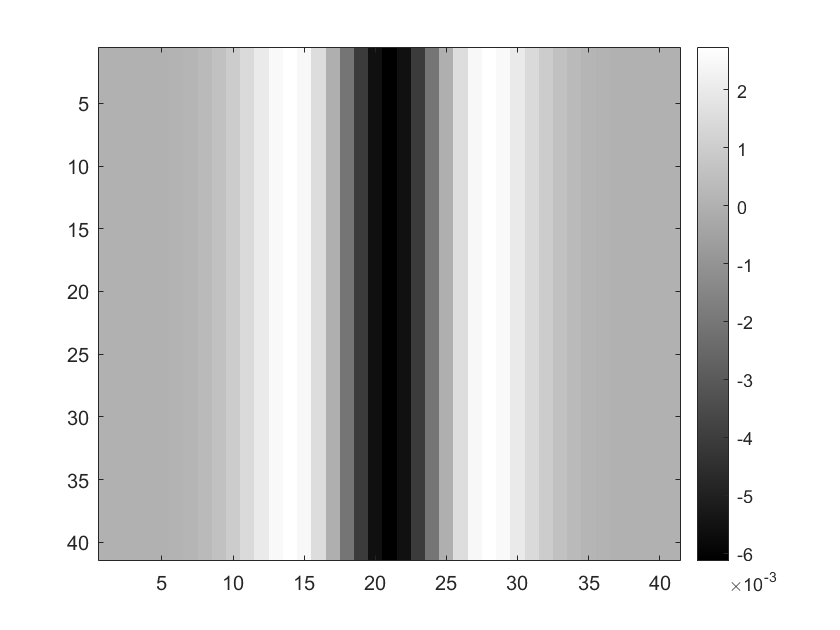

sig = 4;
n = 10*sig+1;
% generate 1D Gaussian
G = exp(-(-(n-1)/2:(n-1)/2).^2/(2*sig*sig));
% normalize 1D Gaussion
G = G/sum(G); 
% take second derivatives of the 1D Gaussian in the x-direction
Gxx = conv(G,[1,-2,1],"same"); 
% construct filter by repeat Gxx n times
F = repmat(Gxx, n, 1);
% show images
imagesc(F); colormap(gray); colorbar

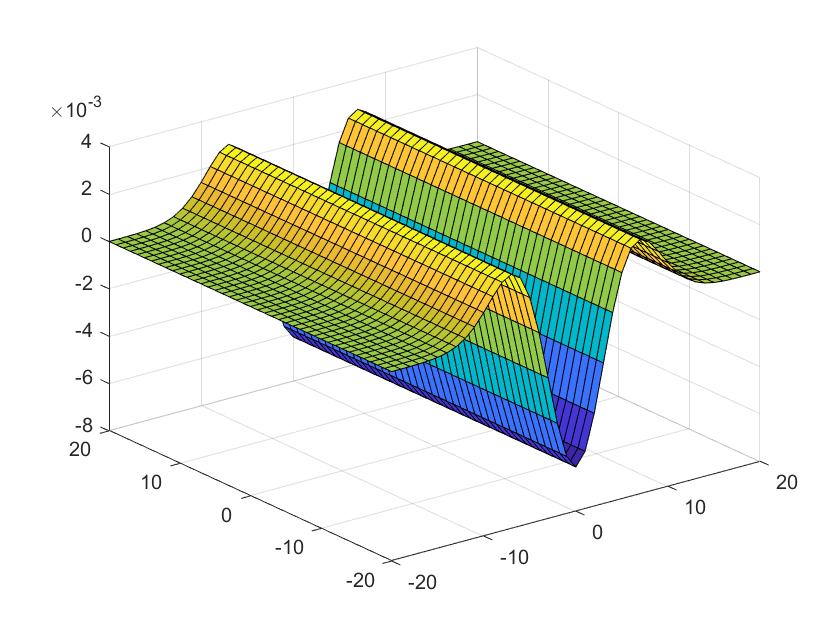

surf((-(n-1)/2:(n-1)/2), (-(n-1)/2:(n-1)/2), F)
colormap("default")

b) Choose sigma_y=6 (>4). Multiply entries of the above filter by a normalized 1D Gaussian in the  y-direction with sigma_y

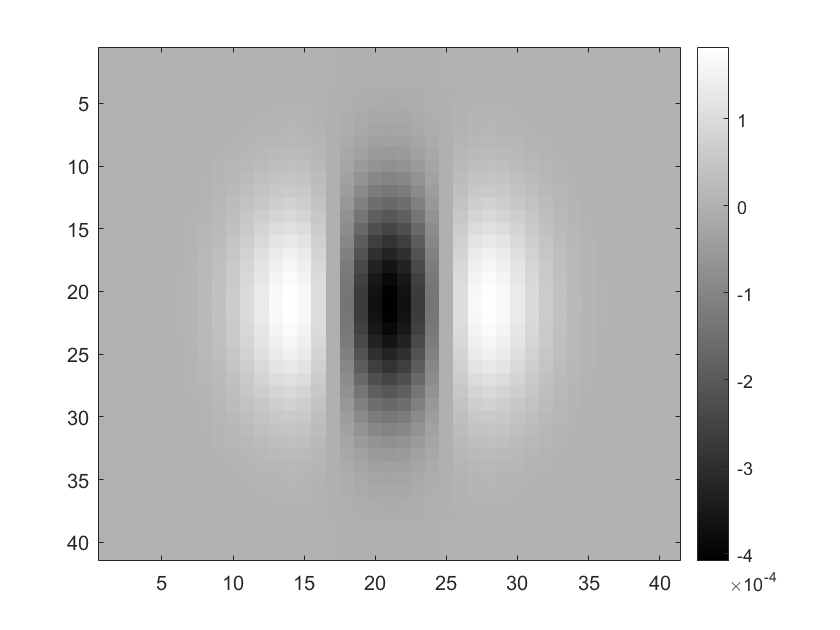

sig_y = 6;
G2 = exp(-(-(n-1)/2:(n-1)/2).^2/(2 *sig_y*sig_y));
G2 = G2/sum(G2);
F2 = diag(G2)*F;
imagesc(F2); colormap(gray); colorbar

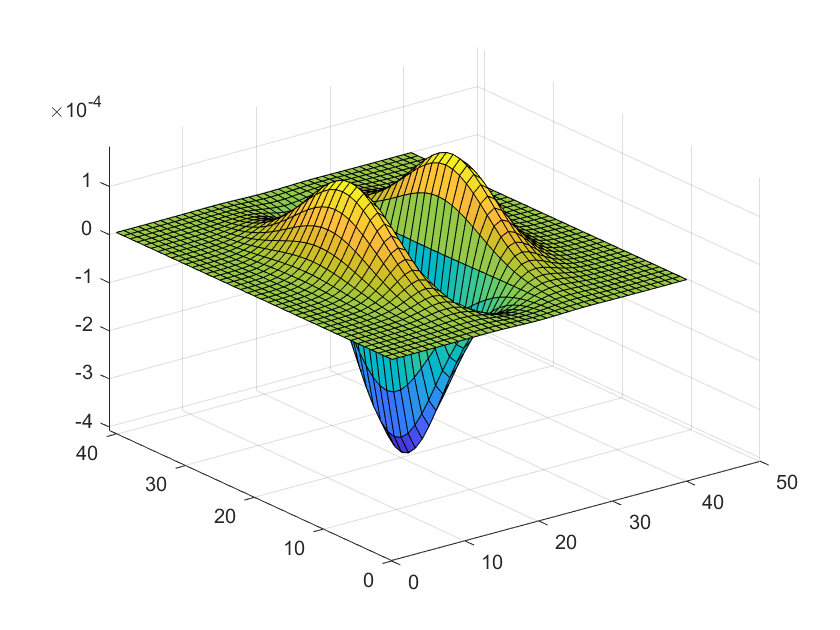

surf(F2); colormap("default")

c) I write the routine to create a rotated filter of size [6sig+1,6sig+1] as a function "rotate", which acceptes four inputs--theta, filter width after rotation, filter width before rotation and the original filter. It is defined at the end.

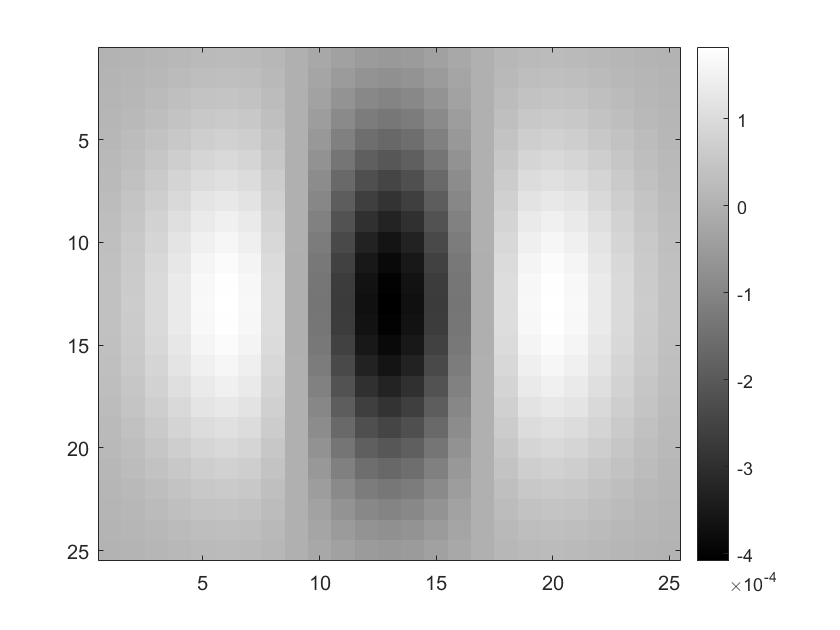

% the 4 rotated filters have width 6sig+1
m = 6*sig+1;

% rotate by 0 degree
F2_rot0 = rotate(0,m,n,F2);
imagesc(F2_rot0); colormap(gray); colorbar

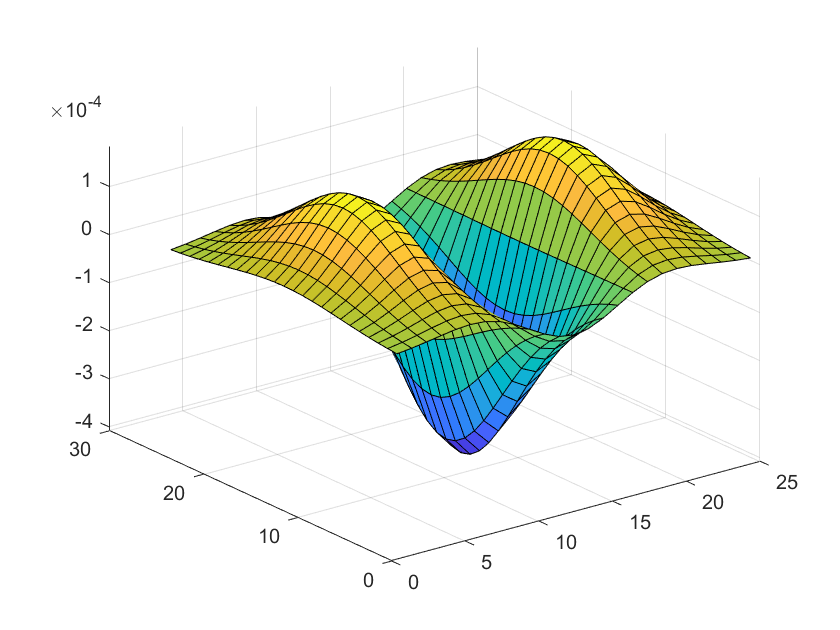

surf(F2_rot0); colormap("default")

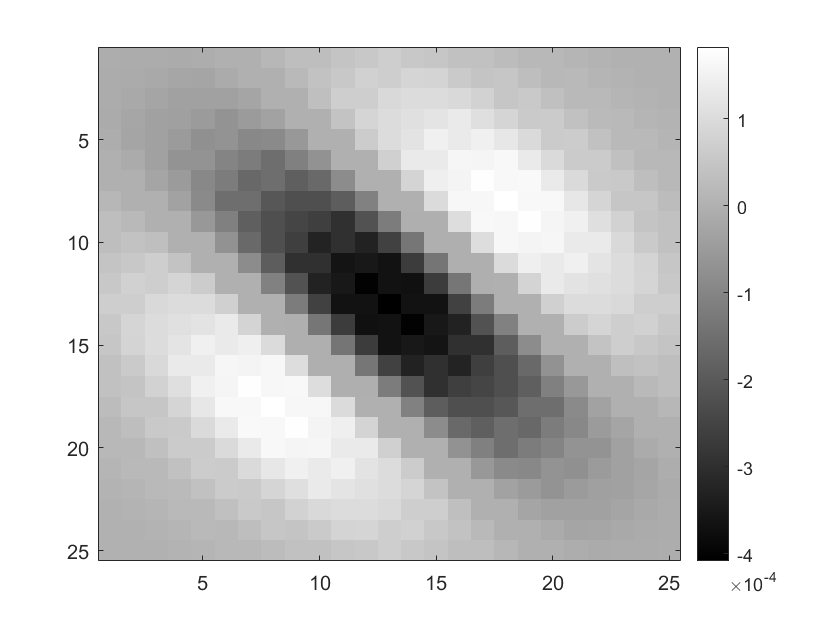


% rotate by 45 degree
F2_rot45 = rotate(45,m,n,F2);
imagesc(F2_rot45); colormap(gray); colorbar

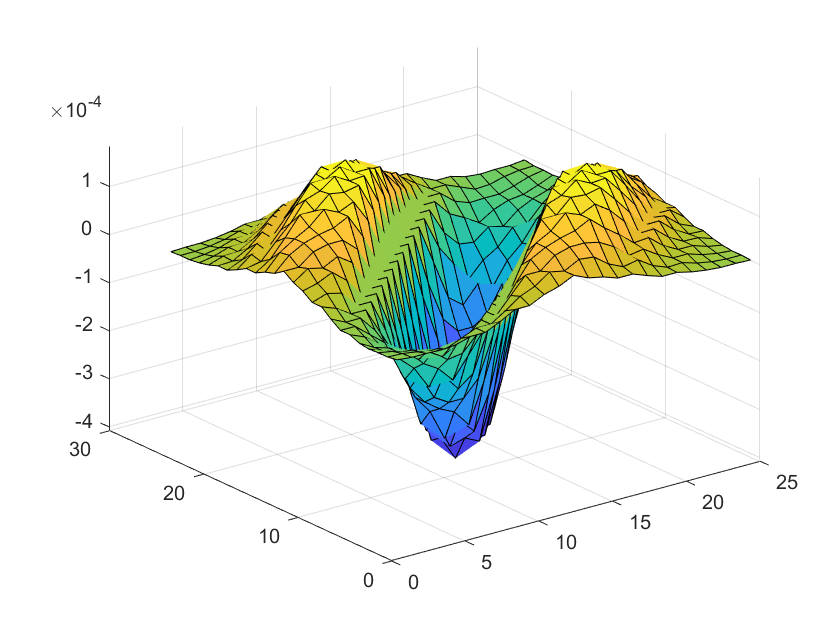

surf(F2_rot45); colormap("default")

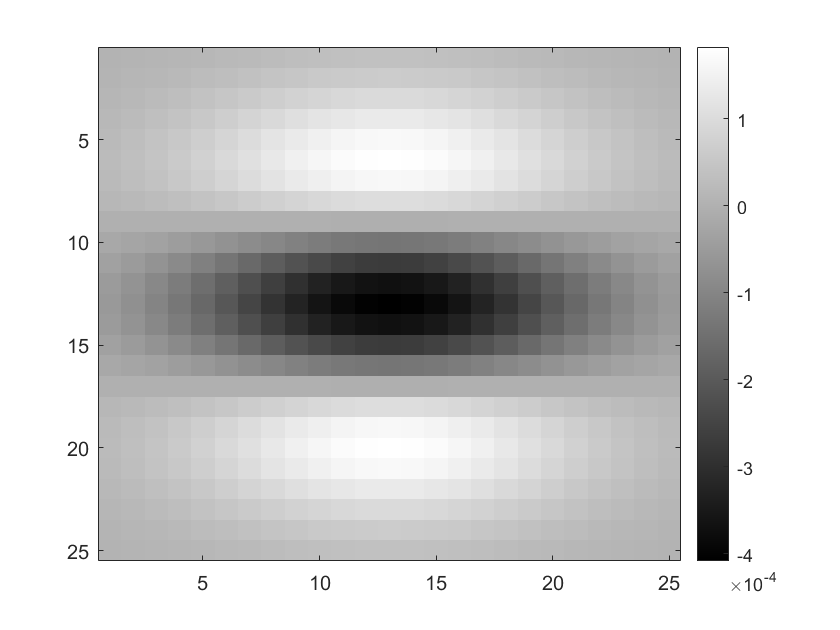


% rotate by 90 degree
F2_rot90 = rotate(90,m,n,F2);
imagesc(F2_rot90); colormap(gray); colorbar

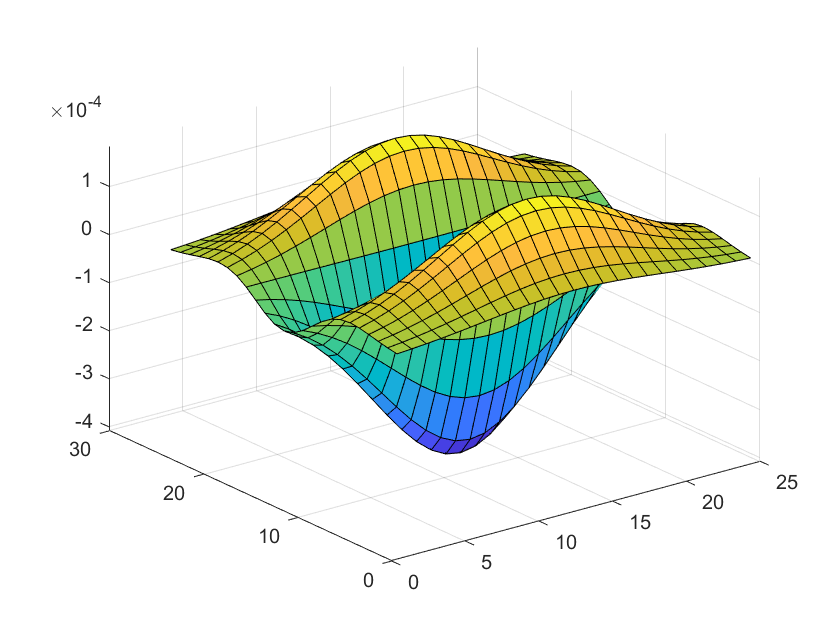

surf(F2_rot90); colormap("default")

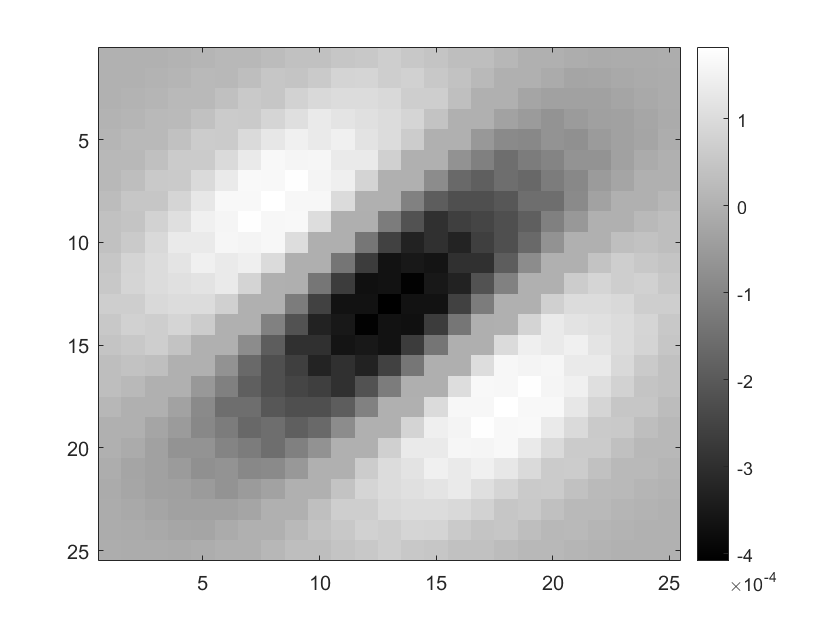


% rotate by 135 degree
F2_rot135 = rotate(135,m,n,F2);
imagesc(F2_rot135); colormap(gray); colorbar

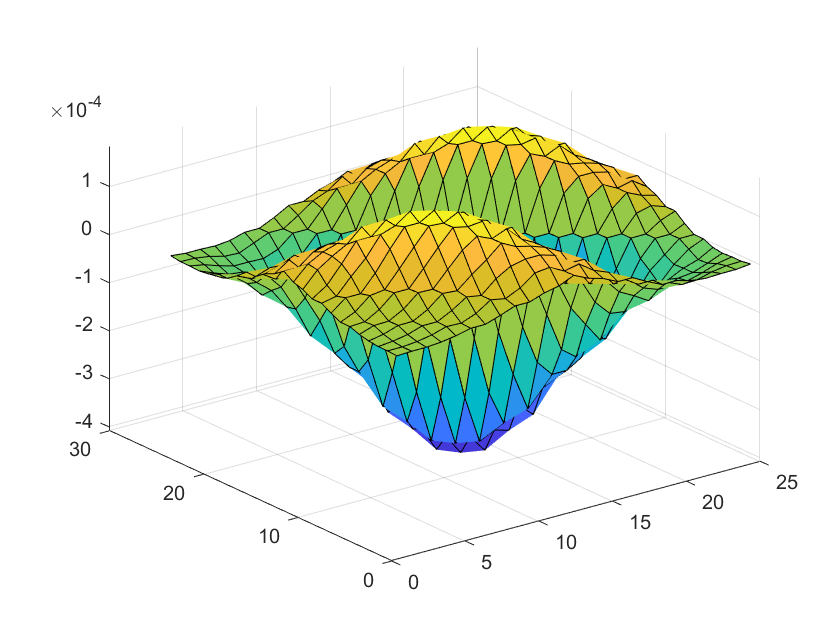

surf(F2_rot135); colormap("default")

d) First filter the image with 4 rotated filters(0,45,90,135-degrees rotation). 

Second,  find the pixels at which there is a zero crossing in either the x or y or  diagonal directions by comparing neighboring pixels and see where the values have different sign.

At last I compose the 4 sets of egdes into one image.

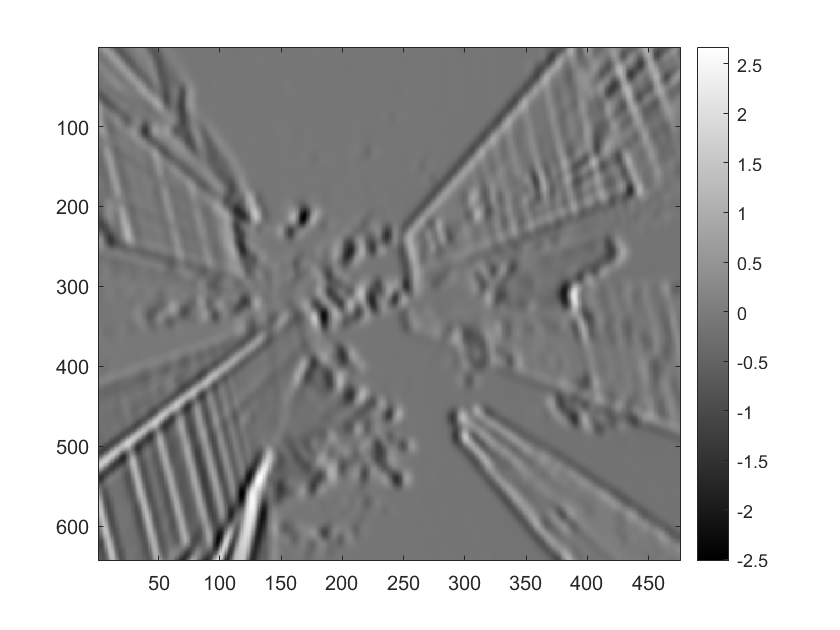

% filter the image with 4 rotated filters and show the results
I = rgb2gray(imread('./skyscrapers.jpg'));

Ie_rot0 = conv2(I,F2_rot0,'valid');
imagesc(Ie_rot0); colormap(gray); colorbar

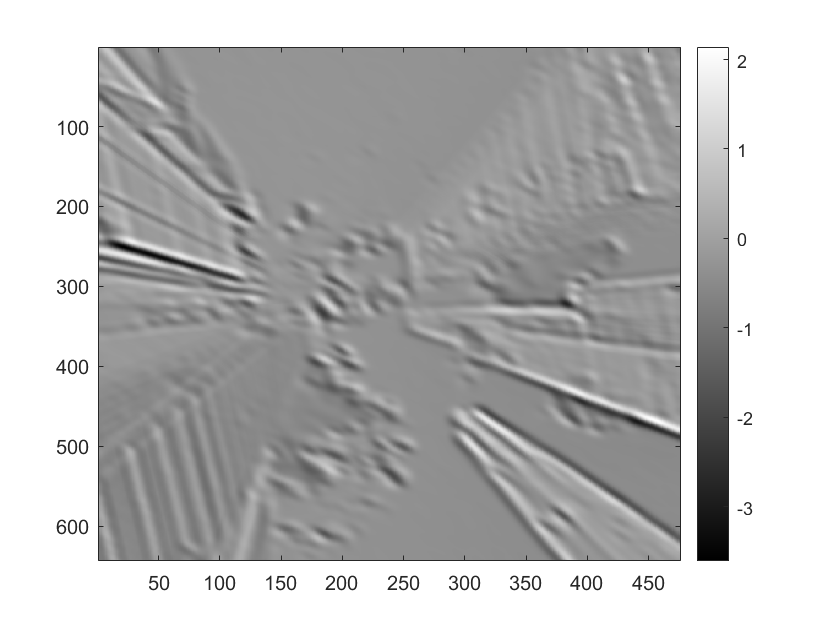


Ie_rot45 = conv2(I,F2_rot45,'valid');
imagesc(Ie_rot45); colormap(gray); colorbar

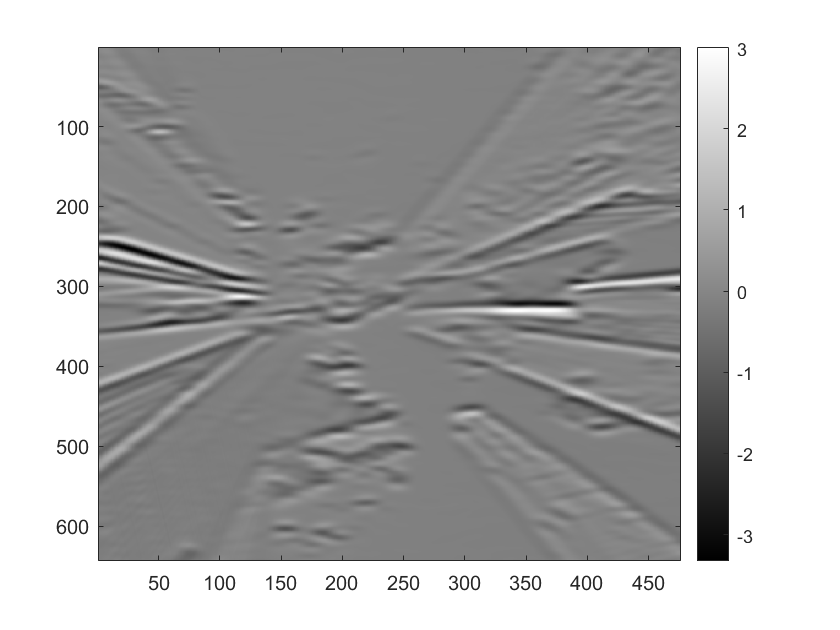


Ie_rot90 = conv2(I,F2_rot90,'valid');
imagesc(Ie_rot90); colormap(gray); colorbar

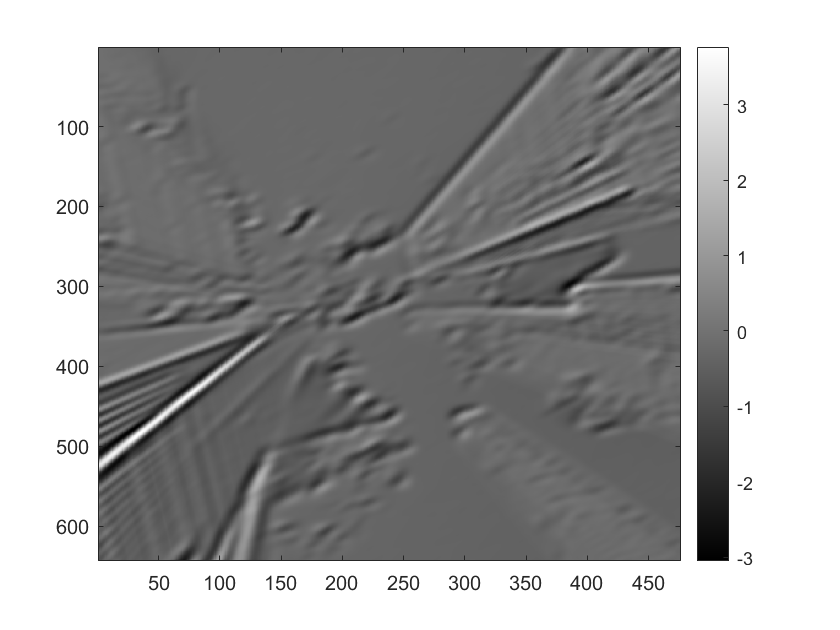


Ie_rot135 = conv2(I,F2_rot135,'valid');
imagesc(Ie_rot135); colormap(gray); colorbar

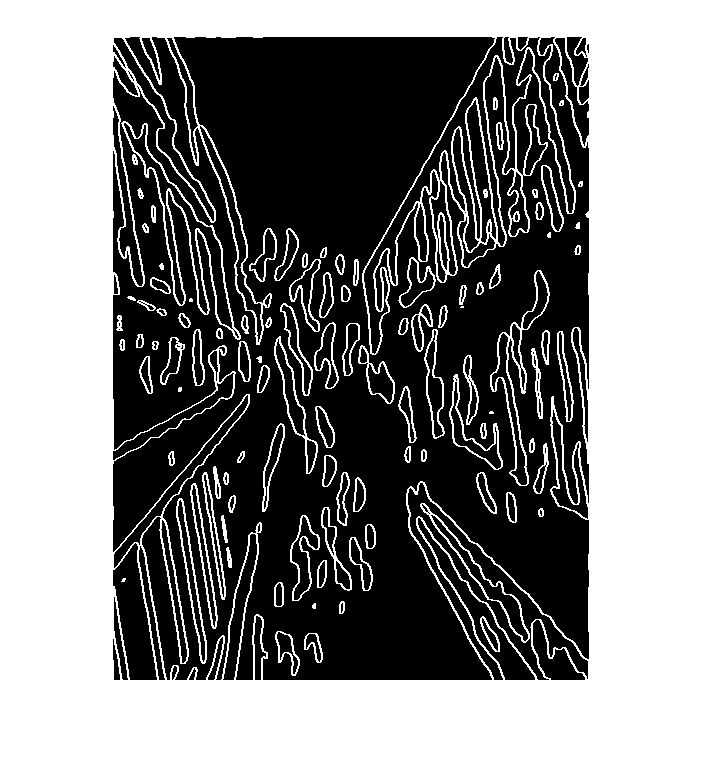


% find zero crossings for filter_rot0
zc_0 = (Ie_rot0 .* circshift(Ie_rot0,1,2) <= 0) | (Ie_rot0 .* circshift(Ie_rot0,1,1) <= 0) | (Ie_rot0 .* circshift(Ie_rot0,[1,1]) <= 0) | (Ie_rot0 .* circshift(Ie_rot0,[1,-1]) <= 0);
imshow(zc_0);

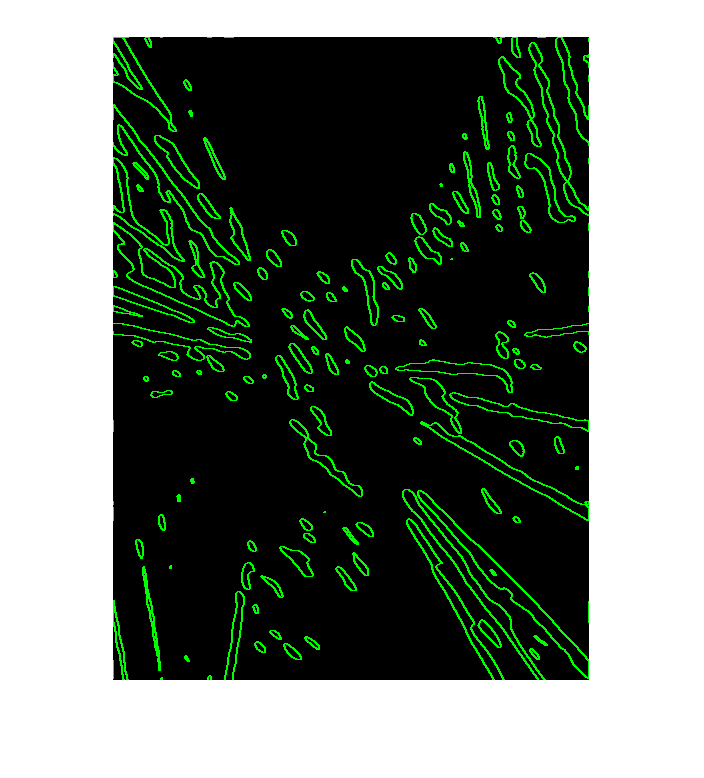


% find zero crossings for filter_rot45
zc_45 = (Ie_rot45 .* circshift(Ie_rot45,1,2) <= 0) | (Ie_rot45 .* circshift(Ie_rot45,1,1) <= 0) | (Ie_rot45 .* circshift(Ie_rot45,[1,1]) <= 0) | (Ie_rot45 .* circshift(Ie_rot45,[1,-1]) <= 0);
imshow(zc_45); colormap([0,0,0; 0,1,0])

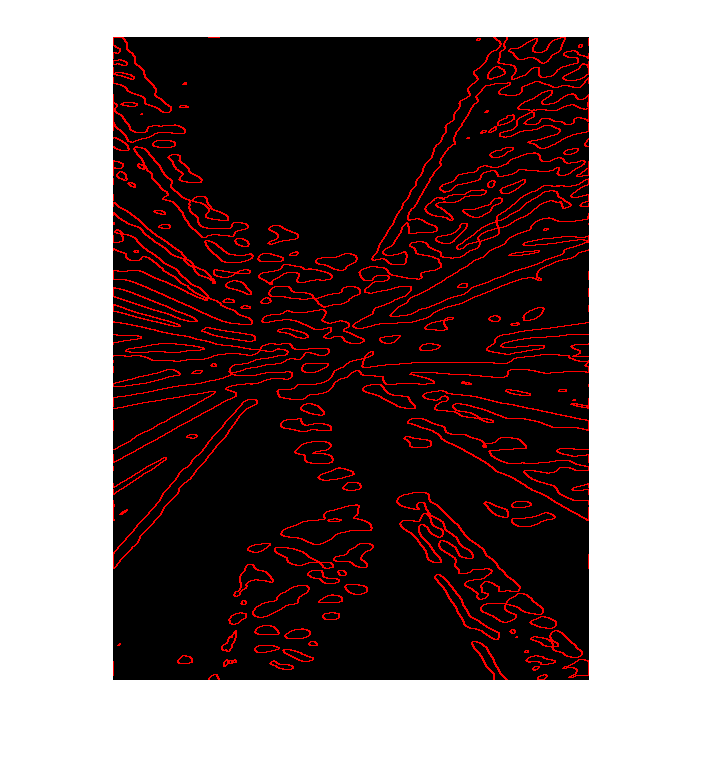


% find zero crossings for filter_rot90
zc_90 = (Ie_rot90 .* circshift(Ie_rot90,1,2) <= 0) | (Ie_rot90 .* circshift(Ie_rot90,1,1) <= 0) | (Ie_rot90 .* circshift(Ie_rot90,[1,1]) <= 0) | (Ie_rot90 .* circshift(Ie_rot90,[1,-1]) <= 0);
imshow(zc_90); colormap([0,0,0; 1,0,0])

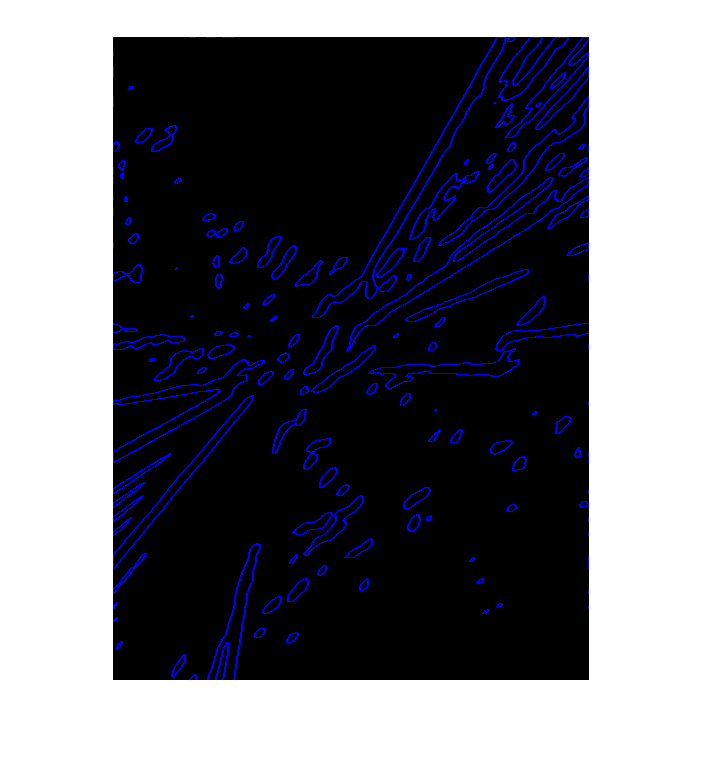


% find zero crossings for filter_rot135
zc_135 = (Ie_rot135 .* circshift(Ie_rot135,1,2) <= 0) | (Ie_rot135 .* circshift(Ie_rot135,1,1) <= 0) | (Ie_rot135 .* circshift(Ie_rot135,[1,1]) <= 0) | (Ie_rot135 .* circshift(Ie_rot135,[1,-1]) <= 0);
imshow(zc_135); colormap([0,0,0; 0,0,1])

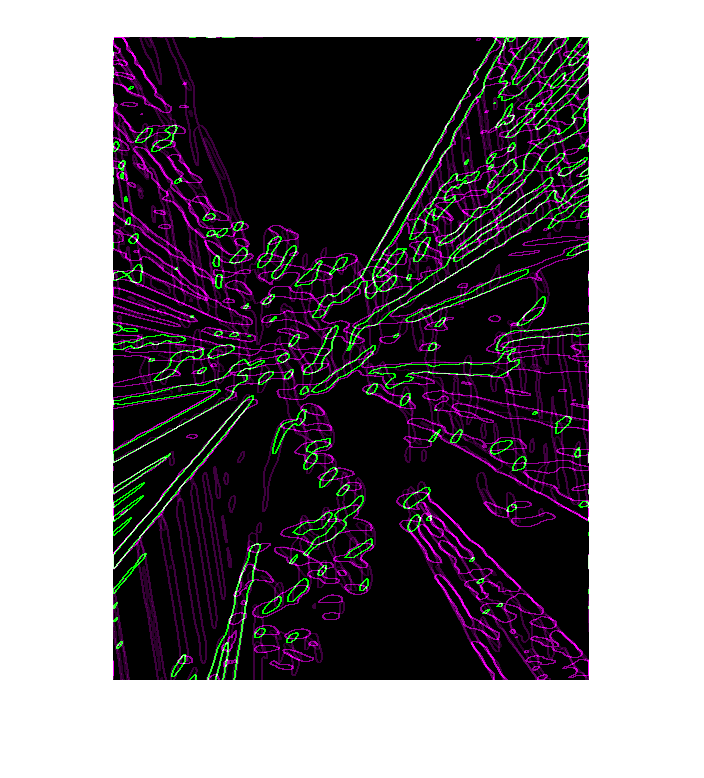


% a composite of 4 sets of zero-crossings
zc = imfuse(zc_135, imfuse(zc_90, imfuse(zc_0,zc_45)));
imshow(zc);

e) Generate a Laplacian of a Gaussian filter with sigma=6 and width=40 (40 is the width after rotation, so I generate a larger filter with width 57). Rotate the filter by degree of 0,45,90 and 135, filter the image with the rotated filters, and find zero-crossings respectively.

As the edge images shown, results in d) are quite different, edges in the direction of the filter rotation are detected most since the filter we designed is oriented. In comparasion, results in e) are quite similar. This somehow proves that the Laplacian is rotation invariant.

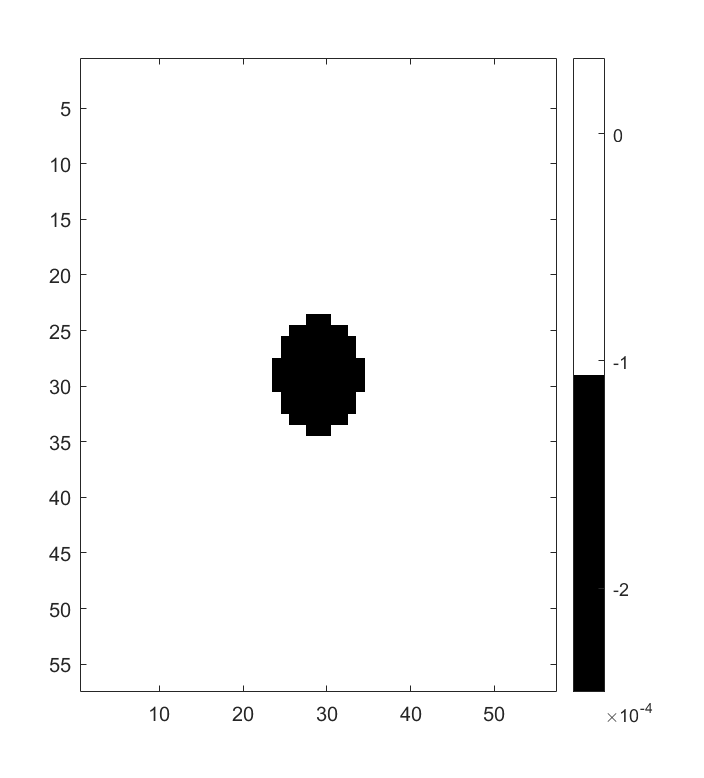

% generate the LoG filter 
Log = fspecial('log',57,6);
imagesc(Log); colormap(gray); colorbar

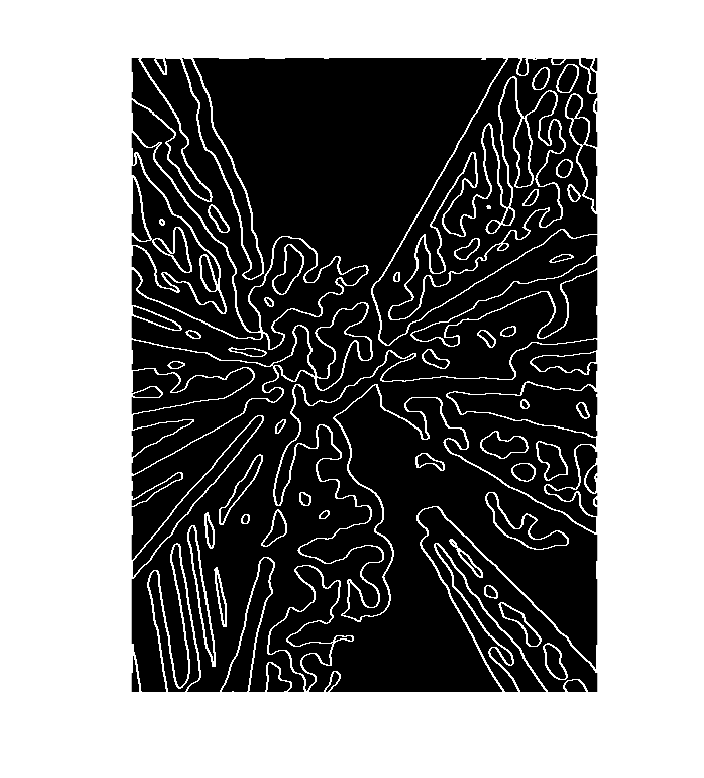


% rotate LoG filter by 0 degree and find zero-crossings
Log_rot0 = rotate(0,40,57,Log);
Ie_log0 = conv2(I,Log_rot0,'valid');
zc_0 = (Ie_log0 .* circshift(Ie_log0,1,2) <= 0) | (Ie_log0 .* circshift(Ie_log0,1,1) <= 0) | (Ie_log0 .* circshift(Ie_log0,[1,1]) <= 0) | (Ie_log0 .* circshift(Ie_log0,[1,-1]) <= 0);
imshow(zc_0);

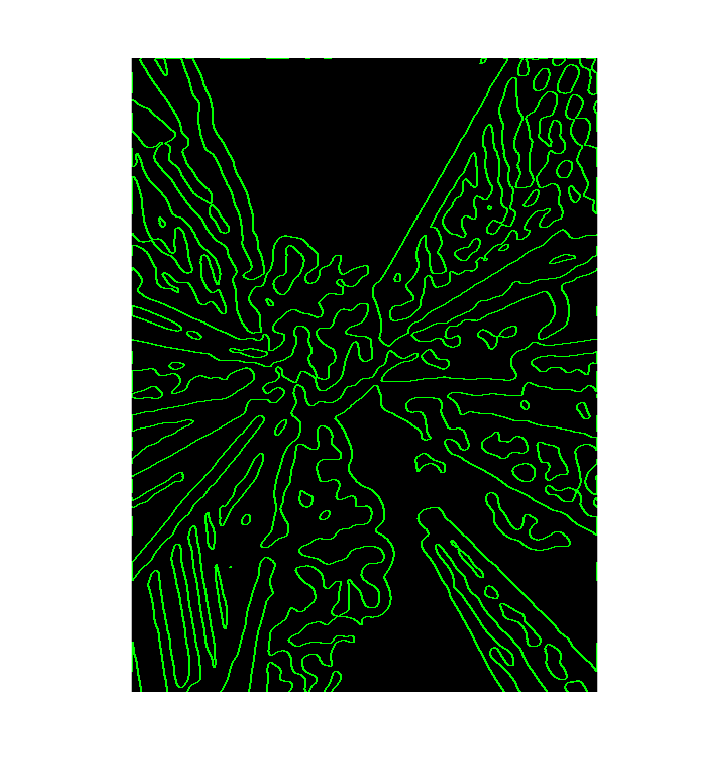


% rotate LoG filter by 45 degree and find zero-crossings
Log_rot45 = rotate(45,40,57,Log);
Ie_log45 = conv2(I,Log_rot45,'valid');
zc_45 = (Ie_log45 .* circshift(Ie_log45,1,2) <= 0) | (Ie_log45 .* circshift(Ie_log45,1,1) <= 0) | (Ie_log45 .* circshift(Ie_log45,[1,1]) <= 0) | (Ie_log45 .* circshift(Ie_log45,[1,-1]) <= 0);
imshow(zc_45); colormap([0,0,0; 0,1,0])

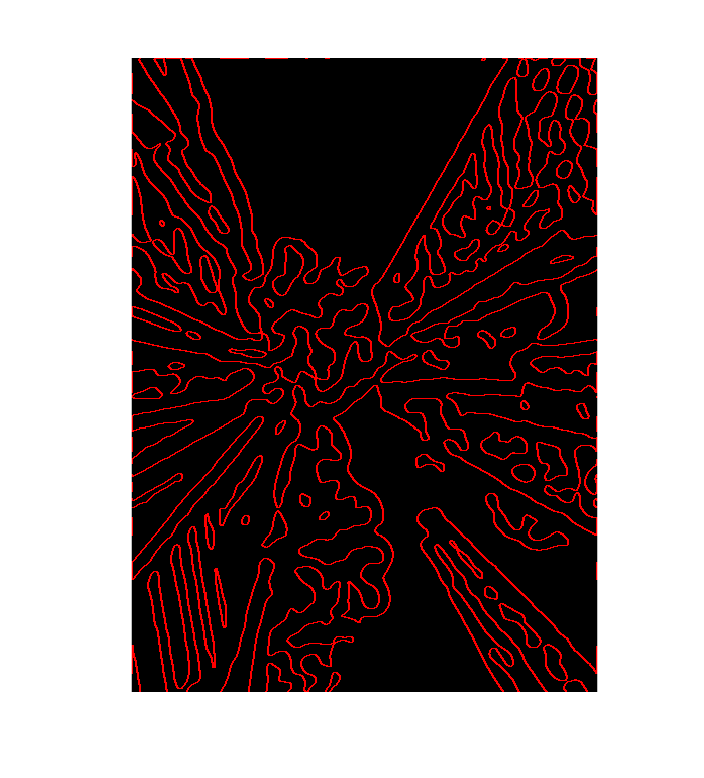


% rotate LoG filter by 90 degree and find zero-crossings
Log_rot90 = rotate(90,40,57,Log);
Ie_log90 = conv2(I,Log_rot90,'valid');
zc_90 = (Ie_log90 .* circshift(Ie_log90,1,2) <= 0) | (Ie_log90 .* circshift(Ie_log90,1,1) <= 0) | (Ie_log90 .* circshift(Ie_log90,[1,1]) <= 0) | (Ie_log90 .* circshift(Ie_log90,[1,-1]) <= 0);
imshow(zc_90); colormap([0,0,0; 1,0,0])

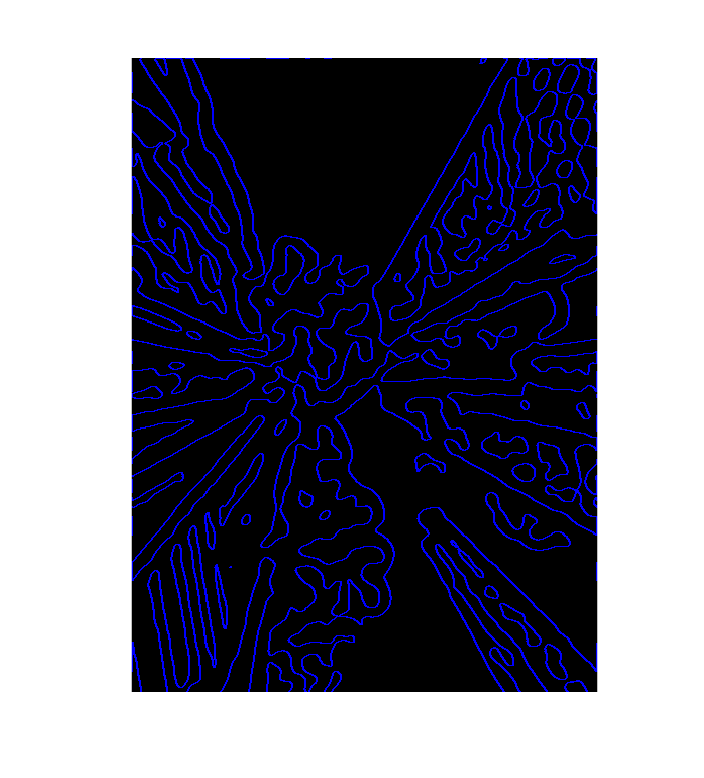


% rotate LoG filter 135 degree and find zero-crossings
Log_rot135 = rotate(135,40,57,Log);
Ie_log135 = conv2(I,Log_rot135,'valid');
zc_135 = (Ie_log135 .* circshift(Ie_log135,1,2) <= 0) | (Ie_log135 .* circshift(Ie_log135,1,1) <= 0) | (Ie_log135 .* circshift(Ie_log135,[1,1]) <= 0) | (Ie_log135 .* circshift(Ie_log135,[1,-1]) <= 0);
imshow(zc_135); colormap([0,0,0; 0,0,1])

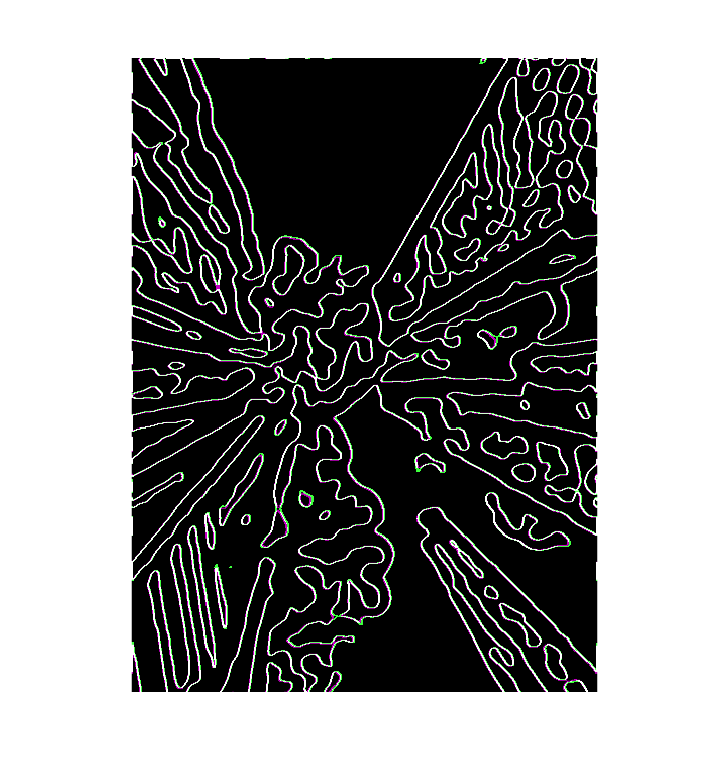


% a composite of the 4 sets of zero crossings
zc = imfuse(zc_135, imfuse(zc_90, imfuse(zc_45,zc_0)));
imshow(zc);

A function defined to rotate a 2D filter. 

Inputs: theta-rotation degree, n-filter width after rotation, n1-filter width before rotation, F-the filter to be rotated

function rotated_F = rotate(theta,n,n1,F)  
    rotated_F = zeros(n,n);
    for i = 1:n
        for j = 1:n
            % put the rotated filter matrix in the standard coordinate system such
            % that the center of the matrix is at (0,0)
            % (x,y) represents coordinates of rotated_F[i,j]
            x = i-(n+1)/2;
            y = j-(n+1)/2;
            % (x1,y1) is where (x,y) is before roatation
            x1 = x*cosd(-theta) - y*sind(-theta);
            y1 = y*cosd(-theta) + x*sind(-theta);
            % round (x1,y1) and move it back since index are positive integers
            i1 = round(x1+(n1+1)/2);
            j1 = round(y1+(n1+1)/2);
            % copy the value from F[i1,j1] to rotated_F[i,j]
            % i.e. form (x1,y1) to (x,y)
            rotated_F(i,j) = F(i1,j1);
        end
    end
end